# APPENDIX

## QUESTION 1.

load dataset1.mat

For :

stdV = 0.047554;
v_vari = stdV*stdV*0.1^2

v_vari = 2.2614e-05

For :

stdR = 0.019155;
stdR*stdR

ans = 3.6691e-04

r_var

r_var = 3.6692e-04

## QUESTION 4

Now that we have the expression for the optimal position estimates, we can start building our vectors and matrices. First we get our y_k measurements from the expression of our observation model:

yk_meas = l - r;

So now we can form the vector of the known data:

T = 0.1;
z = [v*T ; yk_meas];

Then we follow with the transition matrices:

sizet = size(t);

A = ones(sizet(1));
A = tril(A);
A_inv = inv(A);

C = eye(sizet(1));

H = [A_inv ; C];

Then we follow to form the covariance matrix:

Q = eye(sizet(1))*v_vari;

R = eye(sizet(1))*r_var;

zeroMat = zeros (sizet(1));
W = [Q , zeroMat ; zeroMat , R];

This way, we can form the left hand side of the linear systems of equations:

W_inv = inv(W);

LHS = (H.')*W_inv*H;

With the calculation of the left hand side (LHS) matrix, we can plot the sparsity pattern and a focus as follows:

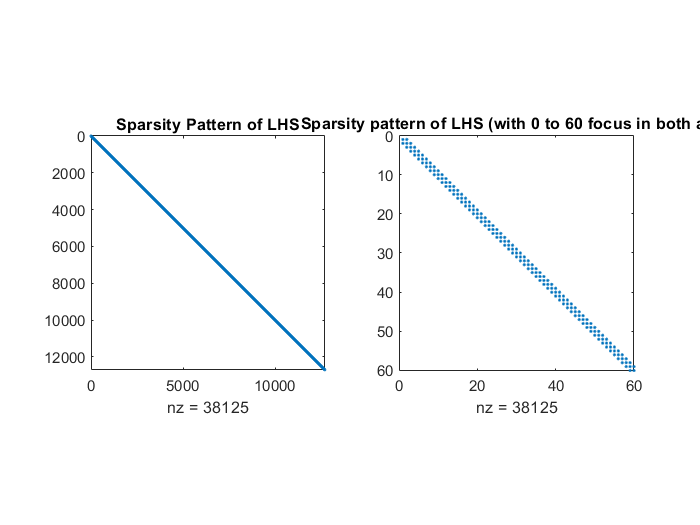

figure
subplot(1,2,1)
spy(LHS)
title('Sparsity Pattern of LHS')
subplot(1,2,2)
spy(LHS)
xlim([0 60])
ylim([0 60])
title('Sparsity pattern of LHS (with 0 to 60 focus in both axis)')

From this point the matrices are transformed to sparse matrices to save memory, and saved in the 'a1Sparse.mat' file.

## QUESTION 5 

RTS Smoother.

clear
load a1Sparse.mat
Q = diag(Q);
R = diag(R);

P_prev = [];
x_prev = [];
K = [];
P_post = [];
x_post = [];
x_final = [];
P_final = [];
V = v*0.1;

Forwards Pass:

delta_flyer = 1000;
for i = 1:sizet(1,1)
    
    if i ==1
        
        P_prev(i,1) = Q(1,1);
        x_prev(i,1) = 0;
        K(i,1) = P_prev(i,1)*(P_prev(i,1)+R(i,1))^-1;
        P_post(i,1) = P_prev(i,1);
        %P_post(i,1) = (1-K(i,1))*P_prev(i,1);
        x_post(i,1) = x_prev(i,1);
        %x_post(i,1) = x_prev(i,1)+K(i,1)*(yk_meas(i,1)-x_prev(i,1));
        
    elseif mod(i,delta_flyer)==0
        
        P_prev(i,1) = P_post(i-1,1) + Q(i,1);
        x_prev(i,1) = x_post(i-1) + V(i,1);
        K(i,1) = P_prev(i,1)*(P_prev(i,1)+R(i,1))^-1;
        P_post(i,1) = (1-K(i,1))*P_prev(i,1);
        x_post(i,1) = x_prev(i,1)+K(i,1)*(yk_meas(i,1)-x_prev(i,1));  
      
    else 
        
        P_prev(i,1) = P_post(i-1,1) + Q(i,1);
        x_prev(i,1) = x_post(i-1) + V(i,1);
        K(i,1) = P_prev(i,1)*(P_prev(i,1)+R(i,1))^-1;
        P_post(i,1) = P_prev(i,1);
        %P_post(i,1) = (1-K(i,1))*P_prev(i,1);
        x_post(i,1) = x_prev(i,1);
        %x_post(i,1) = x_prev(i,1)+K(i,1)*(yk_meas(i,1)-x_prev(i,1));
                
    end    
end

Backwards pass:

x_final(sizet(1,1),1) = x_post(sizet(1,1),1);
P_final(sizet(1,1),1) = P_post(sizet(1,1),1);

for i = sizet(1,1):-1:2
    
    P_final(i-1,1) = P_post(i-1,1)+(P_post(i-1,1)*((P_prev(i,1))^-1))...
        *(P_final(i,1)-P_prev(i,1))*((P_post(i-1,1)*((P_prev(i,1))^-1).'));
    
    x_final(i-1,1) = x_post(i-1,1)+(P_post(i-1,1)...
        *((P_prev(i-1,1))^-1))*(x_final(i,1)-x_prev(i,1));
    
    
    
end

To compare trajectories:

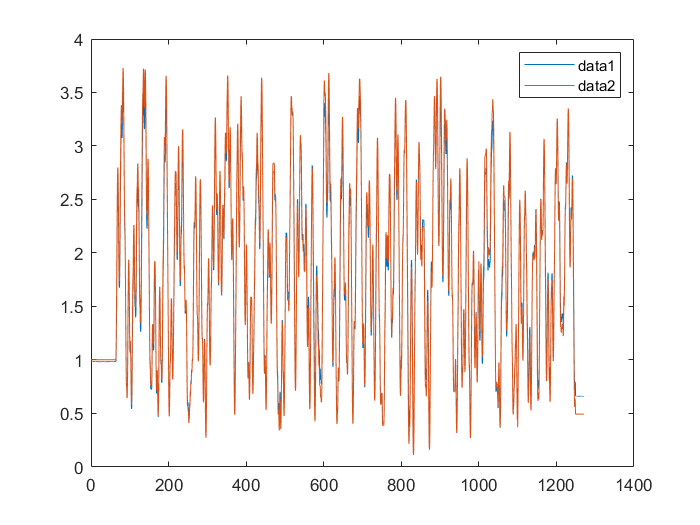

figure
plot(t,x_true)
hold on
plot(t,x_final)
legend

xf = x_final-x_true;
std_dev = sqrt(P_final);

For error plots:

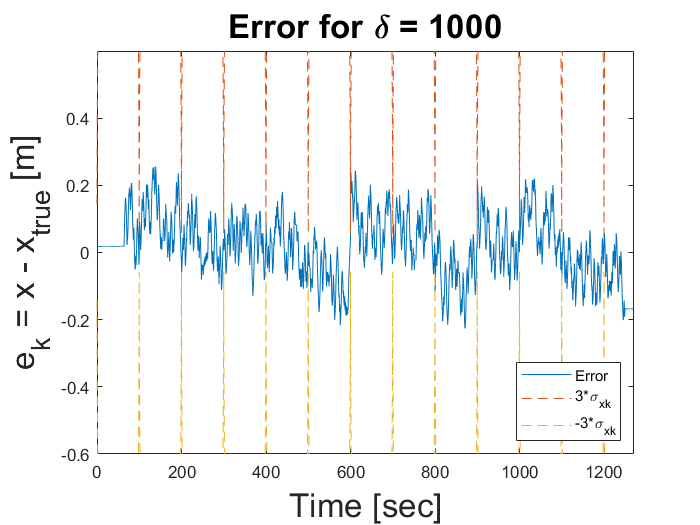

figure
plot(t,xf,t,3*std_dev,'--',t,-3*std_dev,'--')
legend('Error','3*\sigma_{xk}','-3*\sigma_{xk}', 'Location','southeast')
xlim([0,1271])
ylim([-0.6,0.6])
title(['Error for \delta = ' ,num2str(delta_flyer)],'FontSize',20)
xlabel('Time [sec]','FontSize',20)
ylabel('e_{k} = x - x_{true} [m]','FontSize',20)

For histogram error plots:

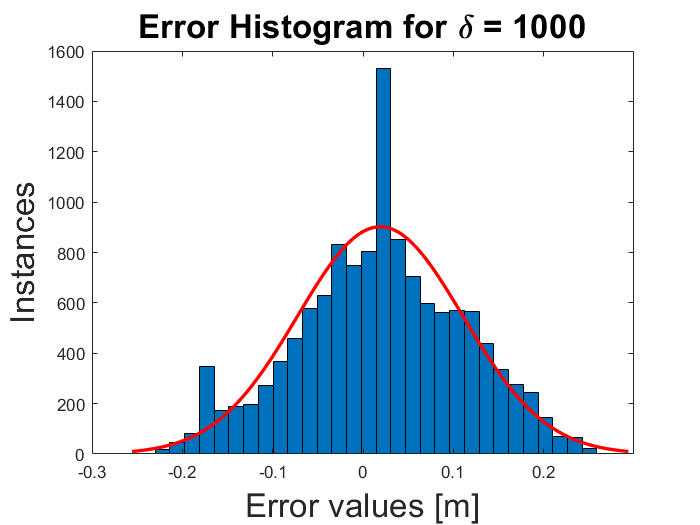

figure
histfit(xf,30)
xlim([-0.3,0.3])
xlabel('Error values [m]','FontSize',20)
ylabel('Instances','FontSize',20)
title(['Error Histogram for \delta = ',num2str(delta_flyer)],'FontSize',20)